# Dynamic Model of Two Wheel Self Balancing Robot

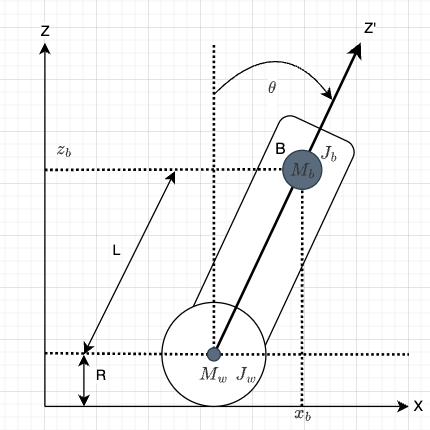

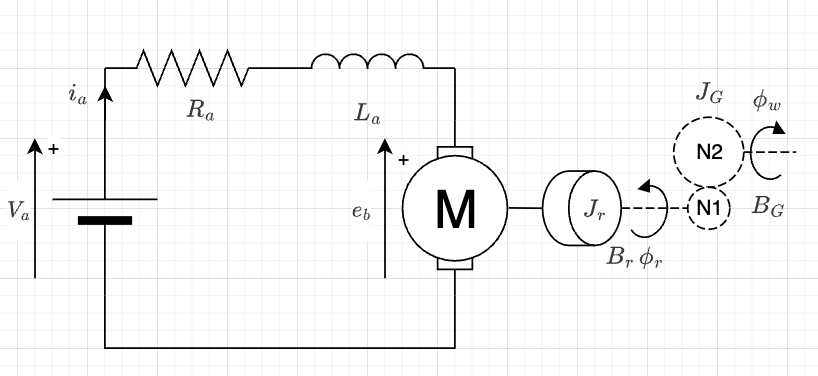

Steady State


$$\mathrm{atan2}\left(-a_x ,a_z \right)$$


$n=\frac{N_2 }{N_1 }$ Gear Teet ratio

$T_m \left(t\right)=K_t \cdot i_a \left(t\right)\;$ torque generate by motor rotor

$J_r \cdot {\ddot{\phi} }_r +B_r \cdot {\dot{\phi} }_r =K_t \cdot i_a \left(t\right)\;$ mechancial torque balance equation

$V_a \left(t\right)=i_a \left(t\right)\cdot R_a +e_b \left(t\right)$ kcl 


$$e_b \left(t\right)=K_e \cdot {\dot{\phi} }_r \;$$
 

$\Omega_w \left(s\right)=\frac{{s\cdot \phi }_r \left(s\right)}{n}$ output shaft speed is less than inpu

$T_w \left(s\right)=n\cdot T_m \left(s\right)-s\cdot B_G \cdot \phi_w$  gearbox  increases torque

$J_{\mathrm{eq}} =J_G +n^2 \cdot J_r$ and $B_{\mathrm{eq}} =B_G +n^2 \cdot B_r$

Full Transfer Function DC Motor


$$\frac{\Omega_w \left(s\right)}{V_a \left(s\right)}=\frac{K_t }{s^2 \cdot L_a R_a +\;s\left(R_a \cdot J_{\mathrm{eq}} +B_{\mathrm{eq}} \cdot L_a \right)+K_t {\cdot K}_e +R_a \cdot B_{\mathrm{eq}} }\cdot \frac{1}{n}$$
 

Reduced order similification for small DC motros with low electical time constant 


$$\frac{\Omega_w \left(s\right)}{V_a \left(s\right)}=\frac{K_t }{\;s\left(R_a \cdot J_{\mathrm{eq}} \right)+K_t {\cdot K}_e +R_a \cdot B_{\mathrm{eq}} }\cdot \frac{1}{n}$$
 

clear
Jr = 3.2284E-5;   % rotor rotational inertia        [Nms^2/rad]
Jg = 3.22E-5;     % Gearbox
Bg = 0.0001;      % vicous friction           [Nms/rad]
Br = 0;
Kt = 0.1;         % Motor Torque constant        []
Ke = 0.1;         % Motor Back EMF constant      []
Ra = 1.2;         % armature resistance       [Ω]
La = 1E-6;        % armature inductance          [H]
N1=1;             
N2 = 20;
n = N2/N1;       % Gear Ratio

Jeq = Jg + n^2*Jr;
Beq = Bg + n^2*Br;
Tstall = 0.15;              %N-m - stall torque
RPMnoload = 6.7*60;         %No-load RPM at Vin=7V.
wnl = (RPMnoload*2*pi)/60;  %No load gearbox output shaft rotation velocity in rad/sec.
Inl = 0.2;                 %No load current into motor, from measurement.
Vin = 7;                   %Volt. Input voltage to armature during test.
Istall =2;                 %Amp, stall armature current.
Ra = Vin/Istall           %Armature resistance.

Ra = 3.5000



Kt = (Tstall/(Vin*n))*Ra   %Armature torque constant.

Kt = 0.0038

Kb = (Vin-Ra*Inl)/(wnl*n)  %Armature back EMF constant.

Kb = 0.0075

s = tf("s"); 
motor_tf = (Kt*n^-1)/((s^2)*(La*Ra) + s*(Ra*Jeq + Beq *La) + Kt*Ke + Ra*Beq)


motor_tf =
 
              0.0001875
  ----------------------------------
  3.5e-06 s^2 + 0.04531 s + 0.000725
 
Continuous-time transfer function.
Model Properties


motor_simp_tf = (Kt*n^-1)/ (s*(Ra*Jeq) + Kt*Ke + Ra*Beq)


motor_simp_tf =
 
       0.0001875
  --------------------
  0.04531 s + 0.000725
 
Continuous-time transfer function.
Model Properties


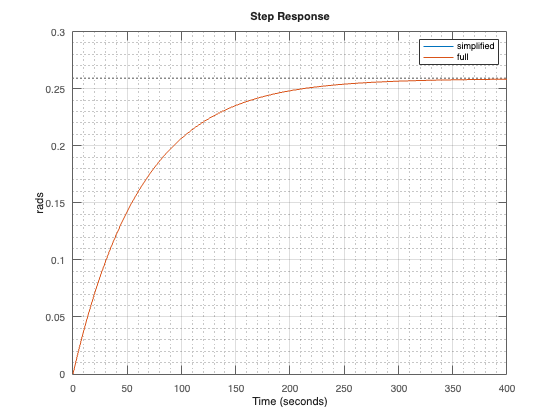


step(motor_simp_tf); ylabel('rads'); hold on; step(motor_tf); legend('simplified', "full"); grid on; grid minor; hold off;